# **MATH1019 Examples:   Plane frames, a simple truss**

## Example from statics:  just-rigid frames

There are many similar examples in engineering textbooks (at 1st year level) like Meriam and Kraige Statics (Wiley, and in this book the examples are in the Chapter on Structures).  Consider the truss shown below:

**Figure 1: **

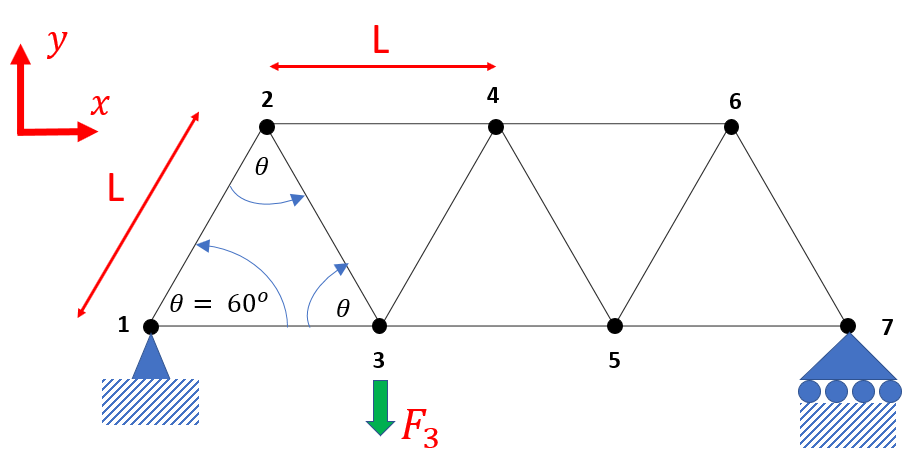

The truss has been secured such that:

- NODE_1 canNOT move in either the X or Y diections

- NODE_7 canNOT move in the Y dirction, but it can move in the X direction

## General Problem statement:

Given: 

- A truss, with specified boundary conditions and specified applied loads at given nodes

Find: 

- The forces acting at the nodes and external reactions at supports

After doing a simpler lead in example, we will return to treating the truss shown in Figure 1.

In real engineering, there are software packages (and some of them are written in MATLAB) which will solve all plane frame problems. One specifies the geometry of the truss or whatever, and where the forces are applied, and the software solves it. However, our goal here is to teach you enough so that you have a reasonable idea of how things work. And, here, after the routine modelling - statics - it just turns into solving a linear system of equations.

In just-rigid frames the bars are rigid and inextensible, and the joints $\bullet$ are smoothly hinged. (Joints are sometimes called ***vertices*** or ***nodes*** or ***pins***). A frame is ***just-rigid*** when the removal of any one of its bars destroys its rigidity.

In an engineering statics course, you might see (perhaps have already)  that a just-rigid frame with ***j*** joints has (***2j-3***) bars. (The proof is essentially done by setting up equations and counting equations and unknowns.),  In Figure 1 there are 7 joints and (2*7-3) = 11 bars.

**Figure 2:  a more general truss (the 7 left most and 5 right most joints have been shown)**

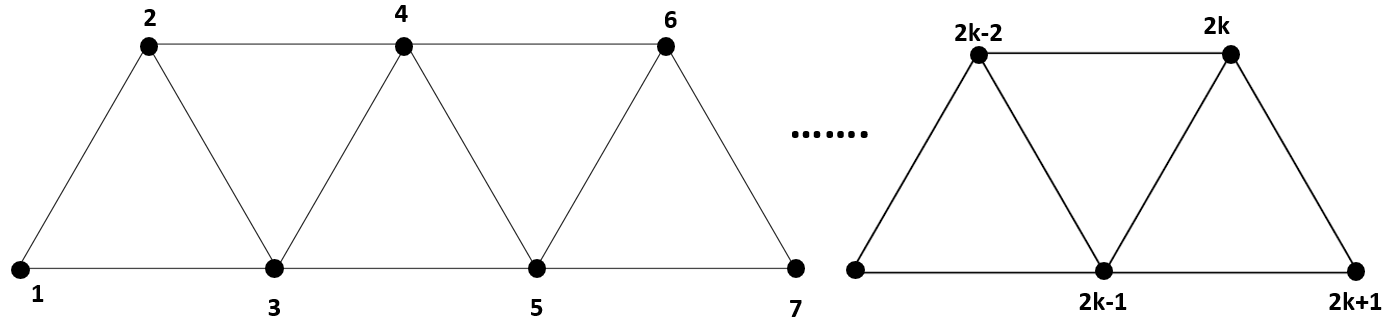

In the diagram above (Figure 2) there are $\left(2k+1\right)=j$ vertices or joints, and the edges count as follows:

-     
$$\matrix{
k & & \text{bottom edges} \cr
k-1 & & \text{top edges} \cr
2k & & \text{sloping edges}
}$$


Hence there is a total count of $\left(4k-1\right)\;=\left(2j-3\right)$ edges .

## The method of joints:

The method of joints for solving for the forces at the joints and the external reactions at the 2 supports (3 unknown components) involves writing down the equations for the equilibrium of forces at each of the$\mathit{\mathbf{j}}$ joints.  For the boundary conditions shown in **Figure 1**, there will be:

- $2\mathit{\mathbf{j}}$ linear equations for the $\left(2\mathit{\mathbf{j}}-3\right)+3=2\mathit{\mathbf{j}}$ unknowns.

Once the joint forces are computed, Newton's 3rd law tells us that equal and opposite forces act on the bars.

So how do we write down the equations? You might revise your statics. A bar is in equilibrium under 2 forces, the reactions at its ends. These 2 forces must be equal in magnitude, act in opposite senses along bar.

- For a bar in tension forces act so that bar tends to be torn in two.

- For a bar in thrust (or compression) forces act so that bar tends to buckle.

Let's look at a simple example.

# Simple Example:   The simple triangular truss 

Consider the following simple truss:

**Figure 3:  Simple truss**

 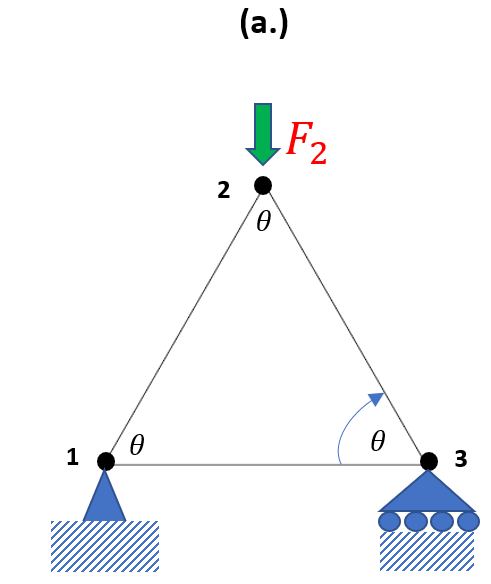          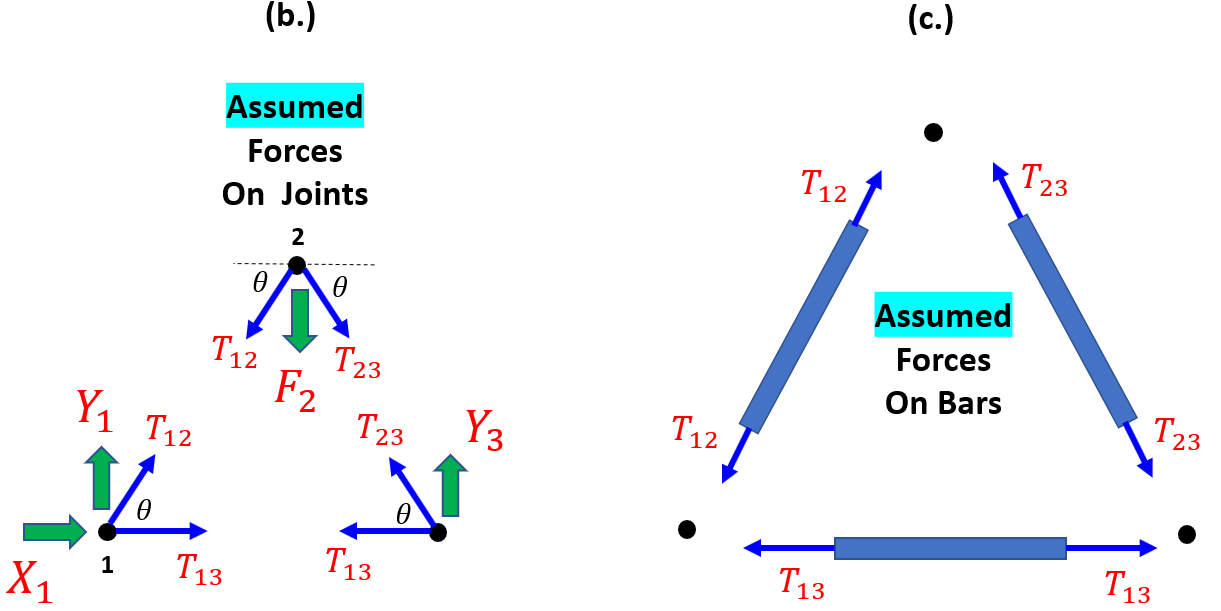

Note:

- We have a single applied load acting vertically down at joint 2

- $X_1 ,Y_1 ,Y_3$ are the reaction forces exerted on the truss from the boundary supports

- Figure 3b shows the assumed forces acting on each joint

- Figure 3c shows the assumed forces acting on each bar (Newton's 3rd Law)

- All members are of equal length and the triangle is an equilateral , ie:  $\theta ={60}^o$.

- We have a single applied load at node 2, indicated by the force $F_2$

- $\mathrm{sin}\left({60}^o \right)=\frac{\sqrt{3}}{2}$   and   $\mathrm{cos}\left({60}^o \right)=\frac{1}{2}$

***NOTE:  ****After computing the values for *$T_{\mathrm{ab}}$*, we'll know if we got the assumed directions correct. Eg: If a specific *$T_{\mathrm{ab}}$* has a negative value then we know that it's direction is opposite to our inital assumed direction.*

## **Hand Solution - Part 1**

Actually it is completely obvious, with the given vertically downward load at the apex that the reactions at the support will be vertically upward and half the magnitude of the load. We can easily confirm that solving the equations by hand.  Consider the structure's **free body** diagram shown below:

**Figure 4:  Free body diagram for Simple truss**

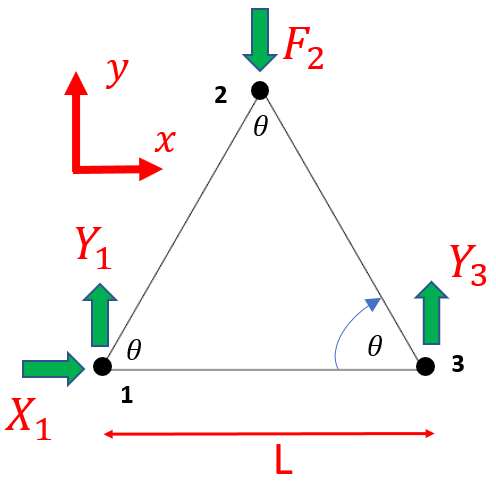  

Taking the sum of the forces in the horizontal  direction:

- 
$${\Sigma \;F_X =0\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;X}_1 =0$$


Taking moments about Node 1:

- 
$$Y_3 \ldotp L=F_2 \ldotp \frac{L}{2}$$
      
$$\Longrightarrow$$
       
$$Y_3 =\frac{1}{2}\ldotp F_2$$


Taking the sum of the forces in the vertical  direction:


$${\Sigma \;F_Y =0\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;Y}_1 \;\;\;+\;\;Y_{3\;\;} =F_2$$
     
$$\Longrightarrow$$
        
$$Y_1 =\frac{1}{2}\ldotp F_2$$


So in summary:

- 
$$Y_3 \;=Y_1 \;=\;\frac{1}{2}\ldotp F_2$$


- 
$$X_1 =0$$


## **Hand Solution - Part 2**

Now let's look at each of the joints  (remember:  $\theta ={60}^o$ and $\mathrm{sin}\left({60}^o \right)=\frac{\sqrt{3}}{2}$   and   $\mathrm{cos}\left({60}^o \right)=\frac{1}{2}$ )

### Joint 1:

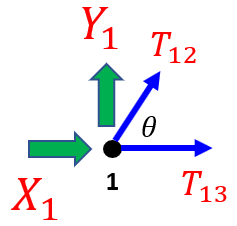

$\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow \;\;\;{X_1 \;\;+\;\;T}_{12} \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;T_{13} \;\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;{X_1 \;\;+\;\;T}_{12} \ldotp \frac{1}{2}\;\;+T_{13} \;=0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;Y_1 \;\;+\;T_{12} \ldotp \mathrm{sin}\left(\theta \right)\;=\;0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;Y_1 \;\;+\;T_{12} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;=0
\end{array}$

### Joint 2:

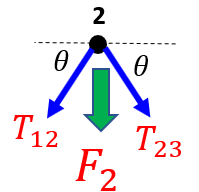

$\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow \;\;\;{\;-T}_{12} \ldotp \cos \left(\theta \right)\;+\;\;T_{23} \ldotp \cos \left(\theta \right)\;\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;{\;T}_{12} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;\;T_{23} \ldotp \left(\frac{1}{2}\right)\;=0
\end{array}$      and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;-T_{12} \ldotp \sin \left(\theta \right)\;+\;{-T}_{23} \ldotp \sin \left(\theta \right)\;\;\;+\;\;{-F}_2 =\;0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;{\;T}_{12} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;+\;\;\;T_{23} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;\;+\;\;{-F}_2 =0
\end{array}$ 

### Joint 3:

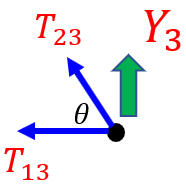

$\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow \;\;\;{\;\;-T}_{23} \ldotp \cos \left(\theta \right)\;+\;\;{-T}_{13} \;\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;{\;\;\;\;\;T}_{23} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;\;\;T_{13} \ldotp \left(-1\right)\;=0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;Y_3 \;\;+\;T_{23} \ldotp \sin \left(\theta \right)\;=\;0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;Y_3 \;\;+\;T_{23} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;=0
\end{array}$

## **Hand Solution - Part 3**

**Joint 1,  and **$\Sigma F_Y$** gives us:**

- $\;Y_1 \;\;+\;T_{12} \ldotp \left(\frac{\sqrt{3}}{2}\right)$ = 0    $\Longrightarrow$    $\;T_{12} \;\;=\;Y_1 \ldotp \left(\frac{-2}{\sqrt{3}}\right)$  $\Longrightarrow$    $\;T_{12} \;\;=\frac{F_2 }{2}\ldotp \left(\frac{-2}{\sqrt{3}}\right)$  $\Longrightarrow$  $T_{12} \;\;={\;F}_2 \ldotp \left(\frac{-1}{\sqrt{3}}\right)$

**Joint 1,  and **$\Sigma F_X$** gives us:**

- 
$${X_1 \;\;+\;\;T}_{12} \ldotp \frac{1}{2}\;\;+T_{13} \;=0$$
     
$$\Longrightarrow \;\;\;0\;+\;\;T_{12} \ldotp \frac{1}{2}\;+T_{13} \;=0\;\;\;\;\Longrightarrow \;\;\;T_{13} =\left(-\frac{1}{2}\right)\ldotp T_{12} \;\;\;\Longrightarrow \;\;\;T_{13} =\;\frac{F_2 }{2\sqrt{3}}$$
  

**Joint 2,  and **$\Sigma F_X$** gives us:**

- 
$${\;T}_{12} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;\;T_{23} \ldotp \left(\frac{1}{2}\right)\;=0$$
     
$$\Longrightarrow \;\;\;T_{23} =\;T_{12} \;\;=\;{\;F}_2 \ldotp \left(\frac{-1}{\sqrt{3}}\right)$$


So in summary, our solution is:

- 
$$\matrix{
X_1 & = & 0 \cr
Y_1 & = & \frac{F_2}{2} \cr
T_{12} & = & \frac{-F_2}{\sqrt{3}} \cr
T_{13} & = & \frac{F_2}{2\sqrt{3}} \cr
T_{23} & = & \frac{-F_2}{\sqrt{3}}  \cr
Y_3 & = & \frac{F_2}{2} 

}$$


Let's redraw the joint force diagrams by applying the correct SIGNS as determined by our solution above.  We'll also draw the corresponding forces acting on each bar:

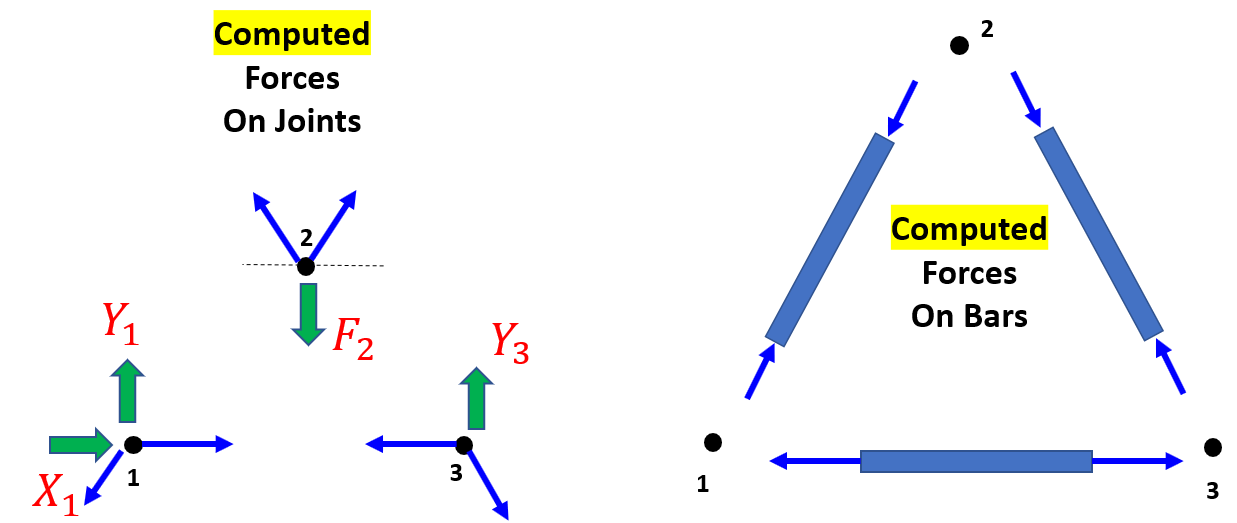

So:

- Bar 1-2  and 2-3  are in compression

- Bar 1-3 is in tension

## MATLAB Solution:

Recall the 6 equations from our Joint analysis:

- 
$${X_1 \;\;+\;\;T}_{12} \ldotp \frac{1}{2}\;\;+\;\;T_{13} \;=0$$


- 
$$Y_1 \;\;+\;T_{12} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;=0$$


- 
$${\;T}_{12} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;\;T_{23} \ldotp \left(\frac{1}{2}\right)\;=0$$


- 
$${\;T}_{12} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;+\;\;\;T_{23} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;\;+\;\;{-F}_2 =0$$


- 
$${\;\;\;\;\;T}_{23} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;\;\;T_{13} \ldotp \left(-1\right)\;=0$$


- 
$$Y_3 \;\;+\;T_{23} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;=0$$


We can write these 6 equations as a matrix equation that has the form:

- $A\ldotp x=f$      where    $x={\left\lbrack \begin{array}{cccccc}
X_1  & Y_1  & T_{12}  & T_{13}  & T_{23}  & Y_3 
\end{array}\right\rbrack }^T$

So it looks like this:

- 
$$\left\lbrack \begin{array}{cccccc}
1 & 0 & \frac{1}{2} & 1 & 0 & 0\\
0 & 1 & \frac{\sqrt{3}}{2} & 0 & 0 & 0\\
0 & 0 & \frac{-1}{2} & 0 & \frac{1}{2} & 0\\
0 & 0 & \frac{-\sqrt{3}}{2} & 0 & \frac{-\sqrt{3}}{2} & 0\\
0 & 0 & 0 & -1 & \frac{-1}{2} & 0\\
0 & 0 & 0 & 0 & \frac{\sqrt{3}}{2} & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
X_1 \\
Y_1 \\
T_{12} \\
T_{13} \\
T_{23} \\
Y_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_2 \\
0\\
0
\end{array}\right\rbrack$$


It is also easy to solve the linear equations in MATLAB. Unless we use the Symbolic Toolbox, we need to assign a numeric value to $F$. 

We'll solve it with $F=1$ and, if we need the result at a different $F$, multiply by that $F$.

s3 = sqrt(3);
A = [ 1,   0,    1/2,   1,      0,   0;
      0,   1,   s3/2,   0,      0,   0;
      0,   0,   -1/2,   0,    1/2,   0;
      0,   0,  -s3/2,   0,  -s3/2,   0;
      0,   0,      0,  -1,   -1/2,   0;
      0,   0,      0,   0,   s3/2,   1;];
  
f = [0;0;0;1;0;0];

Now solve the system:

- $A\ldotp x=f$   using the backslash operator 

x = A \ f

x =    -0.0000
    0.5000
   -0.5774
    0.2887
   -0.5774
    0.5000


***NOTE:  ***

*The matrix A is a banded matrix, as will be all the examples of trusses in this note.*

- [`https://en.wikipedia.org/wiki/Band_matrix`](https://en.wikipedia.org/wiki/Band_matrix)

*There are efficient numerical methods for banded matrices, irrelevant for simple examples like those we are doing. (Basically, under reasonable other conditions, the LU factorization will have the factors L and U also banded.) However, in very large problems efficiency of the numerics can matter.*

Next, let's revisit the slightly harder problem shown in **Figure 1**.

# Harder Example:   The truss 

 Consider the truss shown before in **Figure 1**. All the triangles are equilateral. And recall that

- $\mathrm{sin}\left({60}^o \right)=\frac{\sqrt{3}}{2}$   and  

-  
$$\mathrm{cos}\left({60}^o \right)=\frac{1}{2}$$


**Figure 1: **

## Problem statement:

**Given:**

- the single load $F_3$ acting vertically down at joint 3

- 
$$F_3 =1$$


**Find: **

- the external reactions at supports $X_1 ,Y_1 ,Y_7$ and forces applied to the PIN connections(ie JOINTS) which connect the 11 bars.

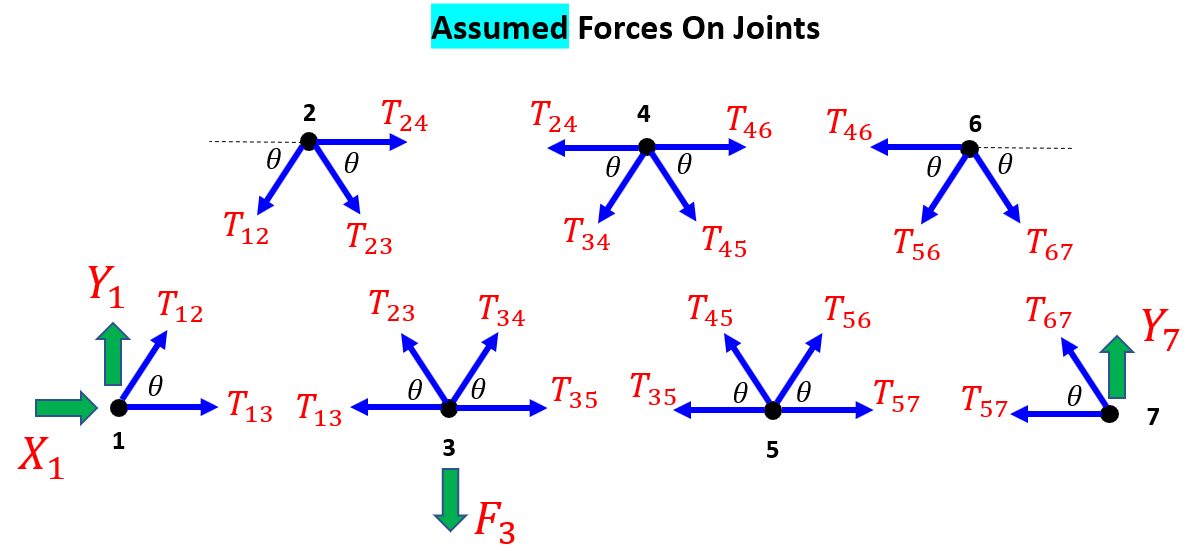

There are 14 linear equations in 14 unknowns. We will take as our vector of unknowns

- 
$${x=\;\left\lbrack X_1 ,\;\;\;Y_1 ,\;\;\;T_{12} ,\;\;\;T_{13} ,\;\;\;T_{23} ,\;\;\;T_{24} ,\;\;\;T_{34} ,\;\;\;T_{35} ,\;\;\;T_{45} ,\;\;\;T_{46} ,\;\;\;T_{56} ,\;{\;T}_{57} ,\;\;T_{67} ,\;\;\;Y_7 \right\rbrack }^T$$


where the notation, superscript T, denotes transpose, and means that the $x$ is a column vector, or

an $n\times 1$ matrix. In matrix form the system is:

- $A\ldotp x=f$   where    $\matrix{
A \quad \text{is an} \quad 14\times 14 \cr
x  \quad \text{is an} \quad 14\times 1 \cr
f  \quad \text{is an} \quad 14\times 1 \cr
}$

So let's look at how we assemble the $A$ and $f$ matrices.

### Assemble the $A$ and $f$ matrices:

First we'll preallocate the matrices to all zeros.  And then we'll fill in the appropriate values. To help us with this, we'll initially use **tables** - this just makes the "row" and "column" assignments sooooo easy to follow.

my_row_names = {'Node_1x','Node_1y','Node_2x','Node_2y','Node_3x','Node_3y', ...
                'Node_4x','Node_4y','Node_5x','Node_5y','Node_6x','Node_6y', ...
                'Node_7x','Node_7y'};

my_col_names = {'X_1', 'Y_1', 'T_12', 'T_13', 'T_23', 'T_24', 'T_34', ...
                'T_35', 'T_45', 'T_46', 'T_56', 'T_57', 'T_67', 'Y_7'};

A_tab        = array2table(zeros(14,14), 'VariableNames', my_col_names, 'RowNames', my_row_names);
f_tab        = array2table(zeros(14,1),  'VariableNames', {'stuff'},    'RowNames', my_row_names);

So initially the $A$ table looks like this:

***NOTE: use the scroll bars to scroll through the table***

A_tab

A_tab = 14×14 table
               X_1    Y_1    T_12    T_13    T_23    T_24    T_34    T_35    T_45    T_46    T_56    T_57    T_67    Y_7
               ___    ___    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ___

    Node_1x     0      0      0       0       0       0       0       0       0       0       0       0       0       0 
    Node_1y     0      0      0       0       0       0       0       0       0       0       0       0   

And initially the $f$ table looks like this:

***NOTE: use the scroll bars to scroll through the table***

f_tab

f_tab = 14×1 table
               stuff
               _____

    Node_1x      0  
    Node_1y      0  
    Node_2x      0  
    Node_2y      0  
    Node_3x      0  
    Node_3y      0  
    Node_4x      0  
    Node_4y      0  
    Node_5x      0  
    Node_5y      0  
    Node_6x      0  
    Node_6y      0  
    Node_7x      0  
    Node_7y      0  


Ok, let's start filling in the appropriate entries into these $A$ and $f$ matrices.  Let's look at the $x$ and $y$ forces acting at each joint (or pin) and write out the equillibrium equations:

cos_theta = cosd(60);  % NOTE the use of cosd which allows DEGREE unit inputs
sin_theta = sind(60);

F3_val    = 1;

### Node #1:

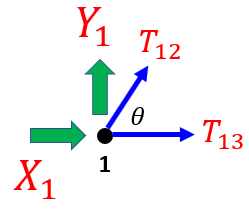

     $\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow X_1 \;+T_{13} +T_{12} \ldotp \mathrm{cos}\left(\theta \right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow X_1 \;+\;T_{13\;} +{\;T}_{12} \ldotp \left(\frac{1}{2}\right)\;=\;0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow Y_1 +T_{12} \ldotp \sin \left(\theta \;\right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow Y_1 \;+\;T_{12} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;=\;0
\end{array}$

A_tab{'Node_1x',  {'X_1','T_13','T_12'} } = [1, 1, cos_theta];
A_tab{'Node_1y',  {'Y_1','T_12'} }        = [1, sin_theta];

### Node #2:

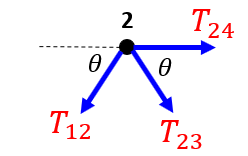

     $\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow T_{24} \;+\;\;T_{23} \ldotp \cos \left(\theta \right)+\;\;{-T}_{12} \ldotp \cos \left(\theta \right)\;\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{24} \;+\;\;T_{23} \ldotp \left(\frac{1}{2}\right)\;+\;\;T_{12} \ldotp \left(\frac{-1}{2}\right)\;\;=0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow {-T}_{12} \ldotp \sin \left(\theta \right)\;+\;\;{-T}_{23} \ldotp \sin \left(\theta \right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{12} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;+\;\;T_{23} \ldotp \left(\frac{-\sqrt{3}}{2}\right)=0
\end{array}$

A_tab{'Node_2x',  {'T_24', 'T_23', 'T_12'} } = [1, cos_theta, -cos_theta];
A_tab{'Node_2y',  {'T_12', 'T_23'} }         = [-sin_theta, -sin_theta];

### Node #3:

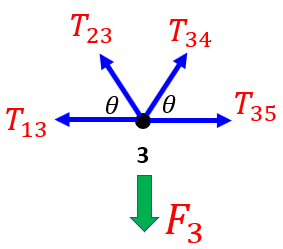

     $\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow {-T}_{13} \;+\;-T_{23} \ldotp \cos \left(\theta \right)+\;\;T_{34} \ldotp \cos \left(\theta \right)\;\;+\;\;T_{35} =0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;T_{13} \ldotp \left(-1\right)\;\;+\;\;T_{23} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;T_{34} \ldotp \left(\frac{1}{2}\right)\;\;+\;\;T_{35} =\;0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;T_{23} \ldotp \mathrm{sin}\left(\theta \right)+\;\;T_{34} \ldotp \mathrm{sin}\left(\theta \right)\;-\;\;F_3 =0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{23} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;+\;\;T_{34} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;+\;\;F_3 \ldotp \left(-1\right)=\;0
\end{array}$

A_tab{'Node_3x',  {'T_13', 'T_23', 'T_34', 'T_35'} } = [-1, -cos_theta, cos_theta, 1];
A_tab{'Node_3y',  {'T_23', 'T_34'} }                 = [sin_theta, sin_theta];

f_tab{'Node_3y', 1} = F3_val;

### Node #4:

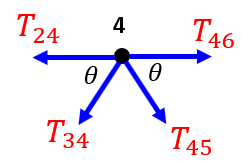

     $\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow {-T}_{24} \;+\;-T_{34} \ldotp \cos \left(\theta \right)+\;\;T_{45} \ldotp \cos \left(\theta \right)\;\;+\;\;T_{46} =0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;T_{24} \ldotp \left(-1\right)\;\;+\;\;T_{34} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;T_{45} \ldotp \left(\frac{1}{2}\right)\;\;+\;\;T_{46} =\;0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;{-T}_{34} \ldotp \sin \left(\theta \right)+\;\;{-T}_{45} \ldotp \sin \left(\theta \right)\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{34} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;+\;\;T_{45} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;=\;0
\end{array}$

A_tab{'Node_4x',  {'T_24', 'T_34', 'T_45', 'T_46'} } = [-1, -cos_theta, cos_theta, 1];
A_tab{'Node_4y',  {'T_34', 'T_45'} }                 = [-sin_theta, -sin_theta];

### Node #5:

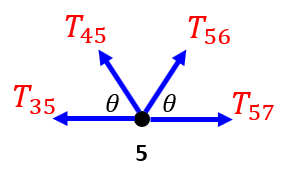

$\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow {-T}_{35} \;+\;-T_{45} \ldotp \cos \left(\theta \right)+\;\;T_{56} \ldotp \cos \left(\theta \right)\;\;+\;\;T_{57} =0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;T_{35} \ldotp \left(-1\right)\;\;+\;\;T_{45} \ldotp \left(\frac{-1}{2}\right)\;\;+\;\;T_{56} \ldotp \left(\frac{1}{2}\right)\;\;+\;\;T_{57} =\;0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow \;T_{45} \ldotp \sin \left(\theta \right)+\;\;T_{56} \ldotp \sin \left(\theta \right)\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{45} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;+\;\;T_{56} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;\;=\;0
\end{array}$

A_tab{'Node_5x',  {'T_35', 'T_45', 'T_56', 'T_57'} } = [-1, -cos_theta, cos_theta, 1];
A_tab{'Node_5y',  {'T_45', 'T_56'} }                 = [sin_theta, sin_theta];

### Node #6:

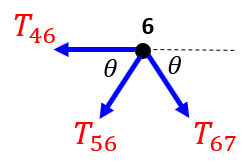

$\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow {-T}_{46} \;+\;\;{-T}_{56} \ldotp \cos \left(\theta \right)+\;\;T_{67} \ldotp \cos \left(\theta \right)\;\;=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{46} \ldotp \left(-1\right)\;+\;\;T_{56} \ldotp \left(\frac{-1}{2}\right)\;+\;\;T_{67} \ldotp \left(\frac{1}{2}\right)\;\;=0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow {-T}_{56} \ldotp \sin \left(\theta \right)\;+\;\;{-T}_{67} \ldotp \sin \left(\theta \right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow T_{56} \ldotp \left(\frac{-\sqrt{3}}{2}\right)\;\;+T_{67} \ldotp \left(\frac{-\sqrt{3}}{2}\right)=0
\end{array}$

A_tab{'Node_6x',  {'T_46', 'T_56', 'T_67'} } = [-1, -cos_theta, cos_theta];
A_tab{'Node_6y',  {'T_56', 'T_67'} }         = [-sin_theta, -sin_theta];

### Node #7:

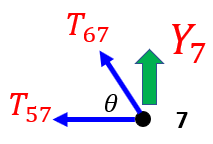

  $\begin{array}{l}
\Sigma \;F_X =0\;\;\Longrightarrow \;-T_{57} \;+{-T}_{67} \ldotp \cos \left(\theta \right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;T_{57} \ldotp \left(-1\right)\;+\;{\;T}_{67} \ldotp \left(\frac{-1}{2}\right)\;=\;0
\end{array}$        and       $\begin{array}{l}
\Sigma \;F_Y =0\;\;\Longrightarrow Y_7 +T_{67} \ldotp \sin \left(\theta \;\right)=0\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow Y_7 \;+\;T_{67} \ldotp \left(\frac{\sqrt{3}}{2}\right)\;=\;0
\end{array}$

A_tab{'Node_7x',  {'T_57','T_67'} } = [-1, -cos_theta];
A_tab{'Node_7y',  {'Y_7','T_67'} }  = [1, sin_theta];

So summarising what we should have is this:

$A = \pmatrix{
% NODE_01x:
1                    &  % X_1
0					&  % Y_1
\left(\frac{1}{2}\right)	&  % T_12      
1					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7			
%----------------------------------
% NODE_01y:
0                    &  % X_1
1					&  % Y_1
\left(\frac{\sqrt{3}}{2}\right)					&  % T_12      
0					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_02x:
                    &  % X_1
					&  % Y_1
\left(\frac{-1}{2}\right)					&  % T_12      
0					&  % T_13      
\left(\frac{1}{2}\right)                    &  % T_23
1					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_02y:
                    &  % X_1
					&  % Y_1
\left(\frac{-\sqrt{3}}{2}\right)					&  % T_12      
0					&  % T_13      
\left(\frac{-\sqrt{3}}{2}\right)                    &  % T_23
0					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_03x:
                    &  % X_1
					&  % Y_1
					&  % T_12      
-1					&  % T_13      
\left(\frac{-1}{2}\right)                     &  % T_23
0					&  % T_24       
\left(\frac{1}{2}\right)					&  % T_34     
1                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_03y:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
\left(\frac{\sqrt{3}}{2}\right)                    &  % T_23
0					&  % T_24       
\left(\frac{\sqrt{3}}{2}\right)					&  % T_34     
0                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_04x:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
-1					&  % T_24       
\left(\frac{-1}{2}\right)					&  % T_34     
0                    &  % T_35      
\left(\frac{1}{2}\right)					&  % T_45       
1					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7
%----------------------------------
% NODE_04y:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
\left(\frac{-\sqrt{3}}{2}\right)					&  % T_34     
0                    &  % T_35      
\left(\frac{-\sqrt{3}}{2}\right)					&  % T_45       
0					&  % T_46      
					&  % T_56     
                    &  % T_57      
					&  % T_67      
				   \cr % Y_7			
%----------------------------------
% NODE_05x:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
                    &  % T_34     
-1                    &  % T_35      
\left(\frac{-1}{2}\right)					&  % T_45       
0					&  % T_46      
\left(\frac{1}{2}\right)										&  % T_56     
1                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_05y:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
\left(\frac{\sqrt{3}}{2}\right)				    &  % T_45       
0					&  % T_46      
\left(\frac{\sqrt{3}}{2}\right)					&  % T_56     
0                    &  % T_57      
					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_06x:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
-1					&  % T_46      
\left(\frac{-1}{2}\right)										&  % T_56     
0                    &  % T_57      
\left(\frac{1}{2}\right)										&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_06y:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
\left(\frac{-\sqrt{3}}{2}\right)					&  % T_56     
0                    &  % T_57      
\left(\frac{-\sqrt{3}}{2}\right)					&  % T_67      
				   \cr % Y_7	
%----------------------------------
% NODE_07x:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
-1                    &  % T_57      
\left(\frac{-1}{2}\right)										&  % T_67      
0				   \cr % Y_7	
%----------------------------------
% NODE_07y:
                    &  % X_1
					&  % Y_1
					&  % T_12      
					&  % T_13      
                    &  % T_23
					&  % T_24       
					&  % T_34     
                    &  % T_35      
					&  % T_45       
					&  % T_46      
					&  % T_56     
0                    &  % T_57      
\left(\frac{\sqrt{3}}{2}\right)					&  % T_67      
1				   \cr % Y_7
} 
$ and $f = \pmatrix{
0 \cr
0 \cr
0 \cr
0 \cr
0 \cr
1 \cr
0 \cr
0 \cr
0 \cr
0 \cr
0 \cr
0 \cr
0 \cr
0 \cr
}$  

So do we ?  Well here's the $A$ table:

***NOTE: use the scroll bars to scroll through the table***

A_tab

A_tab = 14×14 table
               X_1    Y_1      T_12      T_13      T_23      T_24      T_34      T_35      T_45      T_46      T_56      T_57      T_67      Y_7
               ___    ___    ________    ____    ________    ____    ________    ____    ________    ____    ________    ____    ________    ___

    Node_1x     1      0          0.5      1            0      0            0      0            0      0            0      0            0     0 
    Node_1y     0      1      0.86

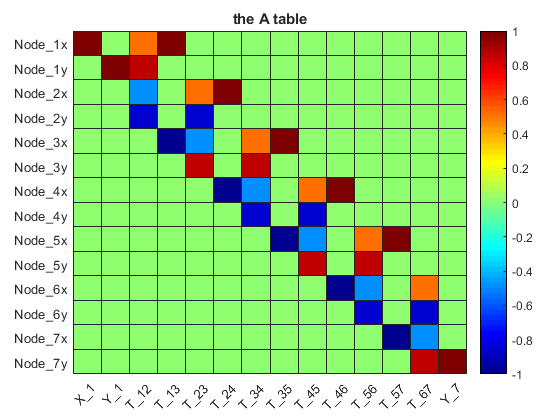

figure; 
heatmap(A_tab{:,:}, 'Colormap', jet, 'YDisplayLabels',my_row_names, 'XDisplayLabels',my_col_names);  
title('the A table')

And similarly here's the $f$ table:

***NOTE: use the scroll bars to scroll through the table***

f_tab

f_tab = 14×1 table
               stuff
               _____

    Node_1x      0  
    Node_1y      0  
    Node_2x      0  
    Node_2y      0  
    Node_3x      0  
    Node_3y      1  
    Node_4x      0  
    Node_4y      0  
    Node_5x      0  
    Node_5y      0  
    Node_6x      0  
    Node_6y      0  
    Node_7x      0  
    Node_7y      0  


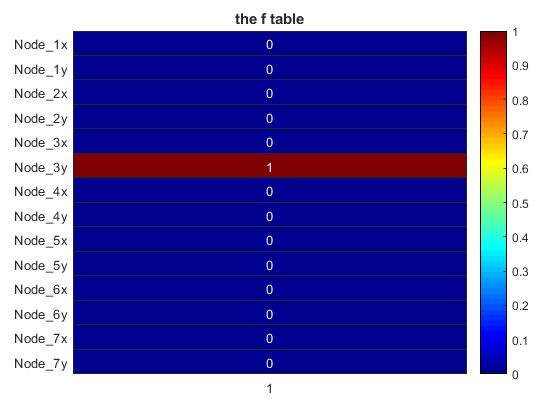


figure; 
heatmap(f_tab{:,:}, 'Colormap', jet,'YDisplayLabels',my_row_names);  
title('the f table')

OK then, let's solve the system of equations.  First extract the data from the tables into "standard" matrix variables:

A = A_tab{:,:};
f = f_tab{:,:};

whos A f

  Name       Size            Bytes  Class     Attributes

  A         14x14             1568  double              
  f         14x1               112  double              



Now solve the system:

- $A\ldotp x=f$   using the backslash operator 

***NOTE: use the scroll bars to scroll through the matrix***

x = A \ f

x =     0.0000
    0.6667
   -0.7698
    0.3849
    0.7698
   -0.7698
    0.3849
    0.5774
   -0.3849
   -0.3849


Again we can use a table to present the solution in a more informative way:

***NOTE: use the scroll bars to scroll through the table***

x_tab = array2table(x,'RowNames', my_col_names)

x_tab = 14×1 table
                x     
            __________

    X_1     1.2779e-17
    Y_1        0.66667
    T_12       -0.7698
    T_13        0.3849
    T_23        0.7698
    T_24       -0.7698
    T_34        0.3849
    T_35       0.57735
    T_45       -0.3849
    T_46       -0.3849
    T_56        0.3849
    T_57       0.19245
    T_67       -0.3849
    Y_7        0.33333


## Hooke's law and elastic pin-jointed frameworks

Elastic framework examples will not be developed here, but it might, for some of you, occur in an engineering course sometime. The pictures one draws in this application area look like those above. Again it is statics. The difference  now is that the bars are elastic, and stretch or compress according to the forces at the joints. Hooke's law ensures that we deal with linear problems. There are treatments of the problem area, a little more advanced than the rigid frames treated here in Strang's *Introduction to Applied Maths* Chpt 2, and in Noble and Daniels *Applied Linear Algebra* Chpt 2.

# Appendix 01:  Compute Reaction forces for Big Truss  

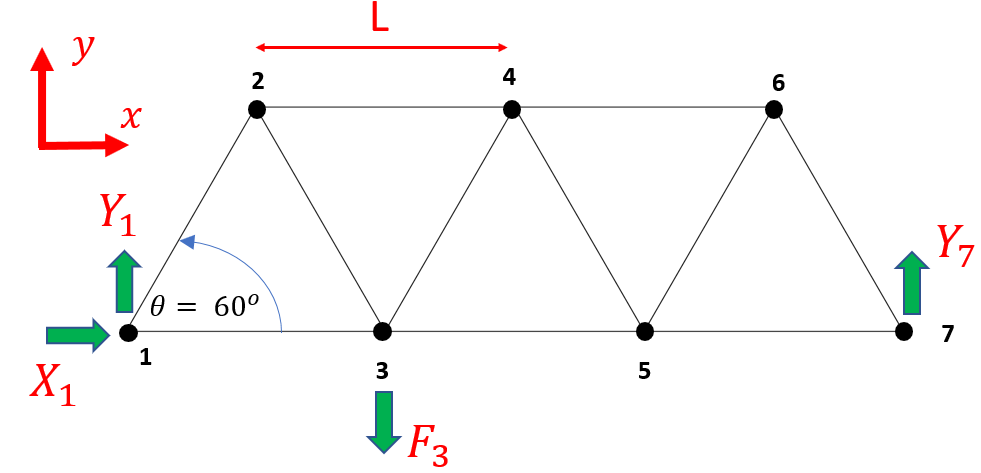

Taking moments about Node 1:

- $F_3 \ldotp L=Y_7 \ldotp 3L$   so    $Y_7 =\frac{1}{3}\ldotp F_3$

Taking the sum of the forces in the vertical direction:

- $Y_1 +Y_7 =F_3$   so   $Y_1 =F_3 -Y_7 =\frac{2}{3}\ldotp F_3$

Taking the sum of the forces in the horizontal  direction:

- 
$$X_1 =0$$


So in summary:

- 
$$Y_7 =\frac{1}{3}\ldotp F_3$$


- 
$$Y_1 =\frac{2}{3}\ldotp F_3$$


- 
$$X_1 =0$$
